# Fit a Nonlinear Model

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

This code loads and plots ocean buoy data. 

time=[0 0.42 0.84 1.26 1.68 2.09 2.51 2.93 3.35 3.77 4.19 4.61 5.03 5.45 5.86 6.28]'

time =          0
    0.4200
    0.8400
    1.2600
    1.6800
    2.0900
    2.5100
    2.9300
    3.3500
    3.7700


height=[0.37 0.49 0.48 0.46 0.33 0.1 -0.12 -0.27 -0.37 -0.51 -0.47 -0.42 -0.2 -0.05 0.18 0.37]'

height =     0.3700
    0.4900
    0.4800
    0.4600
    0.3300
    0.1000
   -0.1200
   -0.2700
   -0.3700
   -0.5100


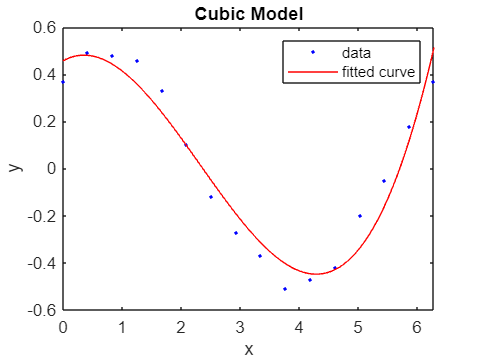

[fCubic,gCubic] = fit(time,height,"poly3");
plot(fCubic,time,height)
title("Cubic Model")

gCubic.rsquare

ans = 0.9467

## Task 1

The variables `time` and `height` are column vectors containing the data for the height of an ocean buoy as a function of time. 

A cubic polynomial has been fit to the data, but you can improve the fit by using nonlinear model. 

Ocean waves are generally assumed to follow a sinusoidal form such as y=Asin(Bx+C), where  A is the amplitude of the wave,  B is the frequency of the wave, and  C is the phase shift of the wave.  

Using the fit type `"sin1"` in the `fit` function will find a model of the form  

y=Asin(Bx+C).

Task

Use the `fit` function to perform nonlinear regression on the variables `time` and `height`. Use the fit type `"sin1"`, and name the two output variables `fSin` and `gSin`. 

[fSin,gSin]=fit(time,height,"sin1")

fSin =      General model Sin1:
     fSin(x) =  a1*sin(b1*x+c1)
     Coefficients (with 95% confidence bounds):
       a1 =       0.503  (0.4824, 0.5236)
       b1 =      0.9926  (0.9707, 1.014)
       c1 =      0.8225  (0.734, 0.911)

gSin = struct with fields:
           sse: 0.0094
       rsquare: 0.9954
           dfe: 13
    adjrsquare: 0.9946
          rmse: 0.0269


## Task 2

Plot the sine model and the data using the `plot` function.

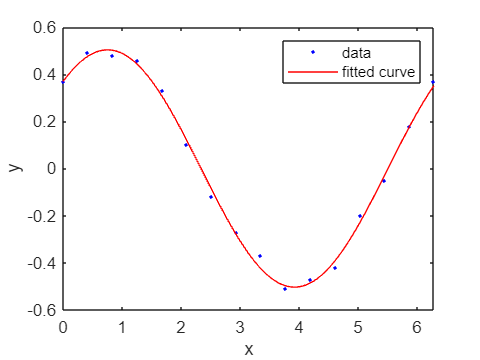

plot(fSin,time,height)

## Task 3

Extract the value of R^2 from `gSin` and save it to the variable `r^2`.

r2=gSin.rsquare

r2 = 0.9954

## Further Practice

You can see from the plot and the R^2 value (0.9954) that the sine model does a better job fitting the buoy data than the cubic model.

Try plotting the residuals of the sine model.

`plot``(``fSin``,``time``,``height``,``"residuals"``)`

Notice that the residual values are normally distributed around the zero line.

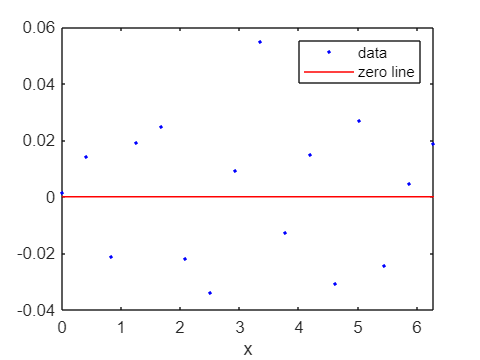

plot(fSin,time,height,"residual")